# C.2a - Projecte Final de Visió per Ordenador

`Joan Bernaus Casadesús i Joan Bennàssar Martín`

`VO - GIA - FIB - UPC`

`Barcelona, a gener de 2025`

## **Enunciat**

L’aplicació coneguda Goodreads té com a característica distintiva un algoritme de reconeixement de llibres basat en imatges de portades. Aquest algoritme identifica la portada, cerca a la seva extensa base de dades el llibre corresponent i, amb aquesta informació, proporciona a l’usuari el títol del llibre, el seu autor, el seu gènere i altres dades d’interès, com ara opinions d’usuaris, entre altres. Els algoritmes més recents combinen tècniques d’emparellament de característiques i reconeixement de caràcters, fet que permet identificar versions de llibres no registrades però que coincideixen positivament pel títol i/o l’autor.

En aquesta primera part de l'exercici 2 es demana desenvolupar un script en MATLAB que desenvolupi un algoritme que determini si els llibres representats a les imatges assignades es troben presents a la base de dades proporcionada (book covers). En aquest cas, es considera que un llibre és a la base de dades si la versió del llibre corresponent a la imatge assignada coincideix amb algun registre de la base de dades. Mostra la imatge de la base de dades amb la qual hi ha un emparellament positiu.

## **1. Carregar les imatges**

% Ruta de la carpeta de referència
reference_folder = "C:/Users/joanb/Desktop/IA/Tercer/VO/PF_VO/EX2/Referencia/";
% Ruta de la base de dades de portades de llibres
database_images_folder = "C:/Users/joanb/Desktop/IA/Tercer/VO/PF_VO/EX2/book_covers/";

% Llistar totes les imatges de la carpeta de referència
reference_files = dir(fullfile(reference_folder, '*.jpg'));

## 2. Desenvolupament de l'algorisme

L'algorisme implementat té com a objectiu determinar si les portades de llibres representades en les imatges assignades es troben a la base de dades proporcionada. Per aconseguir-ho, es basa en la detecció i comparació de característiques visuals mitjançant SIFT (Scale-Invariant Feature Transform).

El procés comença processant cada imatge de referència. Es converteix cada imatge a escala de grisos, si cal, per facilitar el càlcul de les característiques, i s'aplica SIFT per extreure’n punts clau i descriptors

Després, es compara cada imatge de referència amb totes les imatges emmagatzemades a la base de dades, que estan organitzades en subcarpetes. Per a cada imatge de la base de dades, es detecten i extreuen també punts clau i descriptors amb SIFT, i es busquen coincidències entre els descriptors de la imatge de referència i els de la base de dades. Les coincidències es compten i s'utilitzen per determinar quina imatge de la base de dades té més semblança amb la imatge de referència.

Finalment, si el nombre de coincidències supera un llindar mínim establert, es considera que la imatge de referència té una correspondència positiva amb una imatge de la base de dades. Aquest llindar ajuda a descartar coincidències poc significatives

% Llindar mínim de coincidències
min_matches_threshold = 15;

% Recorre cada imatge de la carpeta de referència
for ref_idx = 1:length(reference_files)
    % Obtenir el camí complet de la imatge de referència
    reference_image_path = fullfile(reference_folder, reference_files(ref_idx).name);
    
    % Llegir la imatge de referència
    reference_image = imread(reference_image_path);
    
    % Convertir a escala de grisos si és necessari
    if size(reference_image, 3) == 3
        reference_image_gray = rgb2gray(reference_image);
    else
        reference_image_gray = reference_image;
    end
    
    % Detectar característiques i extreure descriptors amb SIFT
    points_ref = detectSIFTFeatures(reference_image_gray);
    [features_ref, ~] = extractFeatures(reference_image_gray, points_ref);
    
    % Inicialitzar variables per al millor resultat de la imatge actual de referència
    best_match_image = [];
    best_match_path = '';
    max_matches = 0;
    
    % Obtenir totes les subcarpetes de la base de dades
    all_subfolders = dir(database_images_folder);
    all_subfolders = all_subfolders([all_subfolders.isdir]); % Només carpetes
    all_subfolders = all_subfolders(~ismember({all_subfolders.name}, {'.', '..'})); % Excloure . i ..
    
    % Recorre cada subcarpeta
    for subfolder_idx = 1:length(all_subfolders)
        % Obtenir el camí complet de la subcarpeta
        subfolder_path = fullfile(database_images_folder, all_subfolders(subfolder_idx).name);
        
        % Llistar totes les imatges dins de la subcarpeta
        image_files = dir(fullfile(subfolder_path, '*.jpg'));
        
        % Processar cada imatge dins de la subcarpeta
        for i = 1:length(image_files)
            % Obtenir el camí complet de la imatge de la base de dades
            database_image_path = fullfile(subfolder_path, image_files(i).name);
            
            % Llegir la imatge de la base de dades
            database_image = imread(database_image_path);
            
            % Convertir a escala de grisos
            if size(database_image, 3) == 3
                database_image_gray = rgb2gray(database_image);
            else
                database_image_gray = database_image;
            end
            
            % Detectar característiques i extreure descriptors amb SIFT
            points_db = detectSIFTFeatures(database_image_gray);
            if isempty(points_db)
                continue;
            end
            
            [features_db, ~] = extractFeatures(database_image_gray, points_db);
            
            % Emparellar característiques entre la imatge de referència i la de la base de dades
            index_pairs = matchFeatures(features_ref, features_db);
            
            % Comptar el nombre de coincidències
            num_matches = size(index_pairs, 1);
            
            % Actualitzar si trobem una millor coincidència
            if num_matches > max_matches
                max_matches = num_matches;
                best_match_image = database_image;
                best_match_path = database_image_path;
            end
        end
    end

## 3. Resultats

A continuació es mostren els resultats, es mostra la imatge de referència juntament amb la de la base de dades amb més coincidències. Si no s'ha trobat cap imatge amb nombre de coincidències superior al llindar minim, no es mostra cap imatge de la base de dades.

La millor coincidència per a la imatge de referència "118.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Graphic-Novels-Anime-Manga\imagen_881.jpg


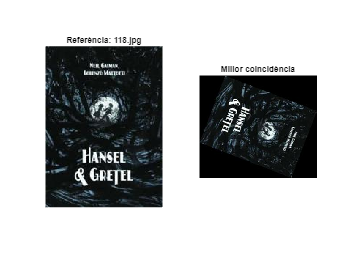

La millor coincidència per a la imatge de referència "142.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Health\imagen_878.jpg


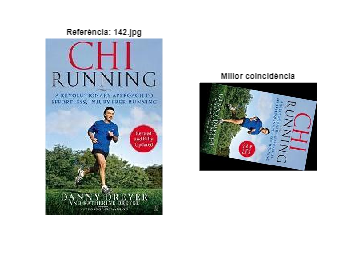

No s'ha trobat cap llibre similar per a la imatge de referència "166.jpg".


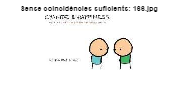

La millor coincidència per a la imatge de referència "190.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Medical\imagen_732.jpg


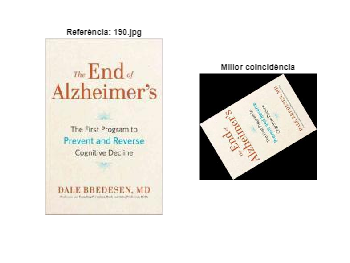

La millor coincidència per a la imatge de referència "214.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Natural-History\imagen_873.jpg


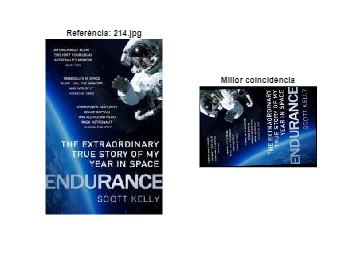

La millor coincidència per a la imatge de referència "22.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Crafts-Hobbies\imagen_186.jpg


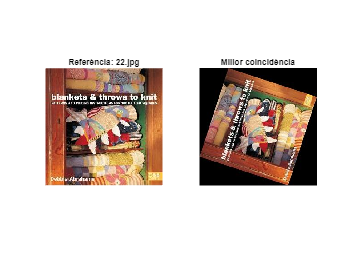

La millor coincidència per a la imatge de referència "238.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Science-Fiction-Fantasy-Horror\imagen_757.jpg


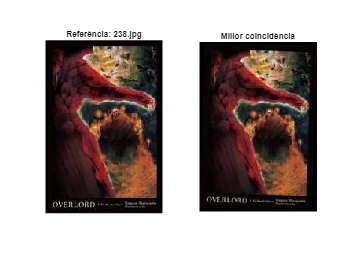

La millor coincidència per a la imatge de referència "262.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Technology-Engineering\imagen_782.jpg


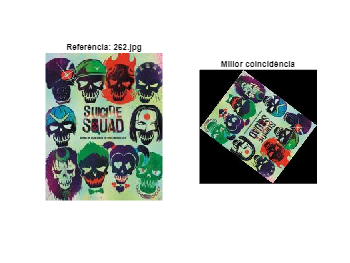

La millor coincidència per a la imatge de referència "286.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Travel-Holiday-Guides\imagen_683.jpg


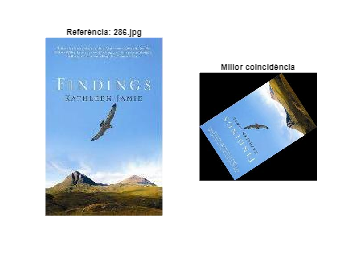

La millor coincidència per a la imatge de referència "46.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Crafts-Hobbies\imagen_526.jpg


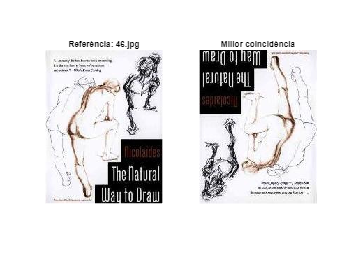

La millor coincidència per a la imatge de referència "70.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Art-Photography\imagen_724.jpg


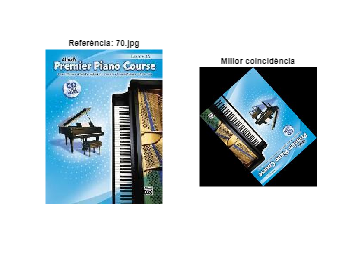

La millor coincidència per a la imatge de referència "94.jpg" és  C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\book_covers\Crime-Thriller\imagen_965.jpg


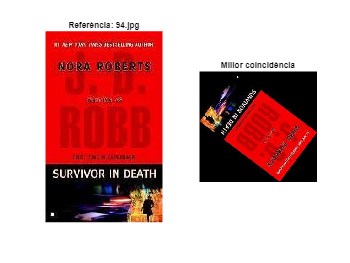

    % Mostrar el resultat per a la imatge de referència actual
    if max_matches >= min_matches_threshold
        fprintf('La millor coincidència per a la imatge de referència "%s" és  %s\n', ...
            reference_files(ref_idx).name, best_match_path);
        
        % Mostrar la imatge de referència i la millor coincidència
        figure;
        subplot(1, 2, 1), imshow(reference_image), title(['Referència: ', reference_files(ref_idx).name]);
        subplot(1, 2, 2), imshow(best_match_image), title('Millor coincidència');
    else
        fprintf('No s''ha trobat cap llibre similar per a la imatge de referència "%s".\n', ...
            reference_files(ref_idx).name);
        % Mostrar només la imatge de referència si no hi ha coincidències suficients
        figure;
        imshow(reference_image), title(['Sense coincidències suficients: ', reference_files(ref_idx).name]);
    end
end